# Four-field Hamiltonian closure of the one-dimensional Vlasov-Poisson equation

Last modified by Cristel Chandre (October 7, 2021)

Comments? [cristel.chandre@univ-amu.fr ](mailto:cristel.chandre@univ-amu.fr)

Requirements: Symbolic Math Toolbox

The Hamiltonian closure is given by $S_4(S_2,S_3)=\sum_{n=0}^\infty f_n(S_2)S_3^{2n}$ where $f_0(S_2)=\kappa S_2^{5/3} $, $f_1(S_2)= \frac{5\kappa  -18S_2^{1/3}}{3S_2(5\kappa  -9S_2^{1/3})}$ and $f_{n+1}=-\frac{1}{(n+1)(2n+1)S_2^{5/3}(5\kappa -9S_2^{1/3})}\left[(4n-1)f_{n}\prime+\sum_{m=1}^n m(12m-7-2n)f_{m}f_{n+1-m} \right]$for $n\geq1.$

Checking the Jacobi identity amounts to checking that $f_n$ satisfies

$(5\kappa S_2^{5/3}-9S_2^2)(n+1)f\prime_{n+1}-(n+1)\frac{5}{3}\kappa S_2^{2/3}f_{n+1}+2 f_n\prime\prime +
\sum_{m=1}^n (6m-n-1) f_m\prime f_{n+1-m}=0$.

The closure function $S_5(S_2,S_3)$ is given by

$6S_5 =12S_2S_3+4S_3\frac{\partial S_4}{\partial S_2}+(5S_4-9S_2^2)\frac{\partial S_4}{\partial S_3}$.

The Casimir invariants are given by


$$C_1=\int {\rm d}x\left[ u+\rho \sum_{n=0}^\infty k_n(S_2)S_3^{2n+1}\right],\\
C_2=\int {\rm d}x \rho \sum_{n=0}^\infty g_n(S_2)S_3^{2n},\\
C_3 = \int {\rm d}x \rho \sum_{n=0}^\infty h_n(S_2)S_3^{2n+1},$$


where $k_0(S_2)= -\frac{3}{S_2^{2/3}(5\kappa - 9S_2^{1/3})}$, $g_0(S_2)=S_2^{1/3}$, $h_0(S_2)=\frac{1}{S_2(5\kappa-9S_2^{1/3})}$ and


$$g_{n+1}=-\frac{1}{(n+1)(2n+1)S_2^{5/3}(5\kappa -9S_2^{1/3})}\left[(4n+1)g\prime_n+\sum_{m=0}^n m(6n+4m+1) f_{n+1-m}g_m \right]\\
h_{n+1}=-\frac{1}{(n+1)(2n+3)S_2^{5/3}(5\kappa-9S_2^{1/3})}\left[(4n+3)h\prime_n+\sum_{m=0}^n (2m+3n+3)(2m+1)f_{n+1-m}h_m \right]\\
k_n=-3\sum_{m=0}^n g_{n-m}h_m$$


**Reference:** C. Chandre, B.A. Shadwick, *Four-field Hamiltonian closure of the one-dimensional Vlasov-Poisson equation*, preprint (2021)

clear
nmax = 15;
display_closure = true;
check_jacobi = true;
casimirs = true;

syms kappa S2 S3 S
s4 = symfun((5*kappa-18*S2^(1/3))/(3*S2*(5*kappa-9*S2^(1/3))),[kappa S2]);
s5 = symfun(5/3*kappa*S2^(2/3),[kappa S2]);
s4b = formula(s4);
for n=1:nmax-1
    g4 = symfun(0,[kappa S2]);
    g5 = symfun(0,[kappa S2]);
    for m=1:n
        g4 = g4+m*(12*m-7-2*n)*s4b(m)*s4b(n+1-m);
        g5 = g5+4*m*(n+1-m)*s4b(m)*s4b(n+1-m);
    end
    g4 = -(g4+(4*n-1)*diff(s4b(n),S2))/((n+1)*(2*n+1)*S2^(5/3)*(5*kappa-9*S2^(1/3)));
    g5 = (diff(s4b(n),S2)+g5)/(2*n+1);
    s4 = [s4,simplify(g4)];
    s5 = [s5,simplify(g5)];
    s4b = formula(s4);
end 
S4 = sum(horzcat(kappa*S2^(5/3),s4b).*S3.^(0:2:2*nmax));
S5 = sum(formula(s5).*S3.^(1:2:2*nmax-1));
if display_closure==true
    displayFormula("S_4(S_2,S_3)=S4")
    displayFormula("S_5(S_2,S_3)=S5")
end

if check_jacobi==true
    cond_val = true;
    for n=1:nmax-1
        g = symfun(0,[kappa S2]);
        for m=1:n
            g = g+(6*m-n-1)*diff(s4b(m),S2)*s4b(n+1-m);
        end
        g = simplify(g);
        cond2 = simplify((5*kappa*S2^(5/3)-9*S2^2)*(n+1)*diff(s4b(n+1),S2)...
            -(n+1)*5/3*kappa*S2^(2/3)*s4b(n+1)+2*diff(s4b(n),S2,2)+g);
        if cond2~=0
            cond_val = false;
            disp(['Obstruction for n=',num2str(n)])
            displayFormula("cond2")
            break
        end
    end
    if cond_val==true
        disp('Jacobi identity: True')
    else
        disp('Jacobi identity: False')
    end
end

Jacobi identity: True


if casimirs==true
    c2 = symfun(-1/(3*S2^(7/3)*(5*kappa-9*S2^(1/3))),[kappa S2]);
    c3 = symfun(2/(3*S2^(11/3)*(5*kappa-9*S2^(1/3))^2),[kappa S2]);
    h0 = symfun(1/(S2*(5*kappa-9*S2^(1/3))),[kappa S2]);
    c2b = formula(c2);
    c3b = formula(c3);
    for n=1:nmax-1
        g2 = symfun(0,[kappa S2]);
        g3 = symfun(3*(n+1)*s4b(n+1)*h0,[kappa S2]);
        for m=1:n
            g2 = g2+m*(6*n+4*m+1)*s4b(n-m+1)*c2b(m);
            g3 = g3+(2*m+1)*(2*m+3*n+3)*s4b(n-m+1)*c3b(m);
        end
        g2 = -(g2+(4*n+1)*diff(c2b(n),S2))/((n+1)*(2*n+1)*(5*kappa*S2^(5/3)-9*S2^2));
        g3 = -(g3+(4*n+3)*diff(c3b(n),S2))/((n+1)*(2*n+3)*(5*kappa*S2^(5/3)-9*S2^2));
        c2 = [c2,simplify(g2)];
        c2b = formula(c2);
        c3 = [c3,simplify(g3)];
        c3b = formula(c3);
    end 
    c1 = -3*h0*S2^(1/3);
    for n=1:nmax
        g1 = c2b(n)*h0+c3b(n)*S2^(1/3);
        for m=1:n-1
            g1 = g1+c2b(n-m)*c3b(m);
        end
        c1 = [c1,simplify(-3*g1)];
        c1b = formula(c1);
    end
    C1 = sum(c1b.*S3.^(1:2:2*nmax+1));
    C2 = sum(horzcat(S2^(1/3),c2b).*S3.^(0:2:2*nmax));
    C3 = sum(horzcat(h0,c3b).*S3.^(1:2:2*nmax+1));
    displayFormula("C_1(S_2,S_3)=C1")
    displayFormula("C_2(S_2,S_3)=C2")
    displayFormula("C_3(S_2,S_3)=C3")
end

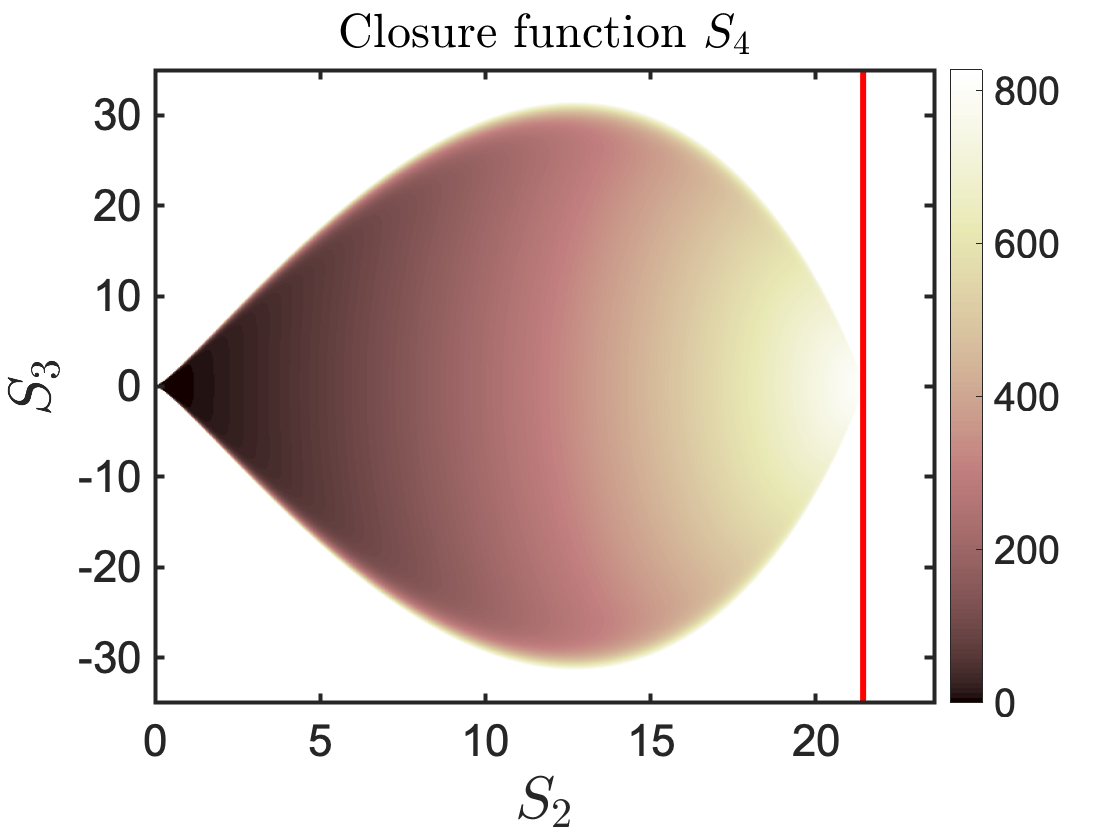

kappa_val = 5;
S3max = 35;
S5max = 1650;

S2max = (5*kappa_val/9)^3;
S4max = kappa_val*S2max^(5/3);
S4m = matlabFunction(subs(S4,kappa,kappa_val));
S5m = matlabFunction(subs(S5,kappa,kappa_val));
s2 = linspace(0,S2max,512);
s3 = linspace(-S3max,S3max,512);
[s2,s3] = meshgrid(s2,s3);
figure
S4vals = S4m(s2,s3);
S4vals(S4vals>=S4max) = NaN;
S4vals(S4vals<=0) = NaN;
pcolor(s2,s3,S4vals)
hold on
plot([S2max S2max],ylim,'r','LineWidth',3)
xlim([0 1.1*S2max])
ylim([-S3max S3max])
shading flat
caxis([0 S4max])
colormap(pink(128));
colorbar
set(gca,'FontSize',22,'FontName','Arial','Box','on','LineWidth',2,'layer','top')
xlabel('$S_2$','Interpreter','latex','FontSize',30);
ylabel('$S_3$','Interpreter','latex','FontSize',30);
title('Closure function $S_4$','interpreter','latex')
hold off

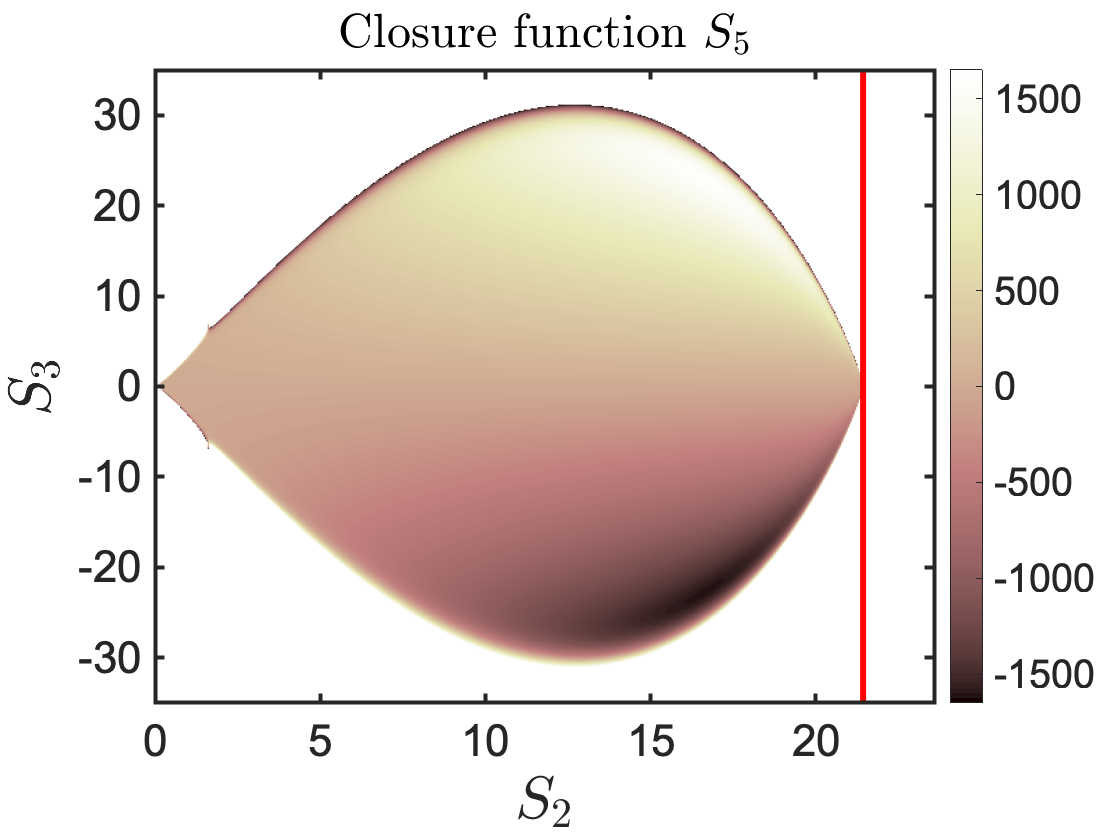

figure
S5vals = S5m(s2,s3);
S5vals(abs(S5vals)>=S5max) = NaN;
pcolor(s2,s3,S5vals)
hold on
plot([S2max S2max],ylim,'r','LineWidth',3)
xlim([0 1.1*S2max])
ylim([-S3max S3max])
shading flat
caxis([-S5max S5max])
colormap(pink(128));
colorbar
set(gca,'FontSize',22,'FontName','Arial','Box','on','LineWidth',2,'layer','top')
xlabel('$S_2$','Interpreter','latex','FontSize',30);
ylabel('$S_3$','Interpreter','latex','FontSize',30);
title('Closure function $S_5$','interpreter','latex')
hold off

Copyright (c) 2021 Cristel Chandre.

All rights reserved.

Redistribution and use in source and binary forms are permitted provided that the above copyright notice and this paragraph are duplicated in all such forms and that any documentation, advertising materials, and other materials related to such distribution and use acknowledge that the software was developed by the CNRS. The name of the CNRS may not be used to endorse or promote products derived from this software without specific prior written permission.

THIS SOFTWARE IS PROVIDED "AS IS" AND WITHOUT ANY EXPRESS OR IMPLIED WARRANTIES, INCLUDING, WITHOUT LIMITATION, THE IMPLIED WARRANTIES OF MERCHANTABILITY AND FITNESS FOR A PARTICULAR PURPOSE.